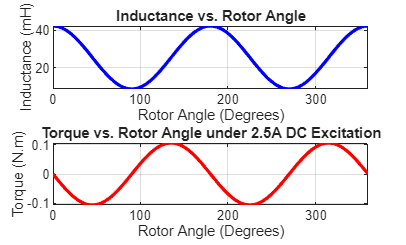

% MATLAB Code for Corrected Inductance and Torque Plotting
% Define the rotation angle array (0 to 360 degrees)
theta_deg = 0:1:360;
theta_rad = deg2rad(theta_deg);

% Corrected System Parameters
L_max = 0.0424;  % Maximum inductance in Henrys
L_min = 0.00848; % Minimum inductance in Henrys
I = 2.5;         % Constant DC current in Amperes

% Inductance Equation Components
L_0 = (L_max + L_min) / 2;
L_2 = (L_max - L_min) / 2;

% Calculate Inductance (converted to mH for plotting)
L_theta = (L_0 + L_2 * cos(2 * theta_rad)) * 1000; 

% Calculate Torque (Nm)
T_e = -(I^2) * L_2 * sin(2 * theta_rad);

% Create Plot Figure
figure('Name', 'Reluctance Motor Characteristics', 'Color', 'w');

% Plot Inductance
subplot(2,1,1);
plot(theta_deg, L_theta, 'LineWidth', 2, 'Color', 'b');
title('Inductance vs. Rotor Angle');
xlabel('Rotor Angle (Degrees)');
ylabel('Inductance (mH)');
xlim([0 360]);
grid on;

% Plot Torque
subplot(2,1,2);
plot(theta_deg, T_e, 'LineWidth', 2, 'Color', 'r');
title('Torque vs. Rotor Angle under 2.5A DC Excitation');
xlabel('Rotor Angle (Degrees)');
ylabel('Torque (N.m)');
xlim([0 360]);
grid on;